% Take the firsimage and convert in rgb2 gray


img = cell(1,6);
for ind = 1:6
    img{ind} = imread(strcat("ur_c_s_03a_01_L_03", num2str((ind+75)),".png"));
    img{ind} = colorToDouble(img{ind});
end





Find the red car

Initializing Window Designer..

... done. 


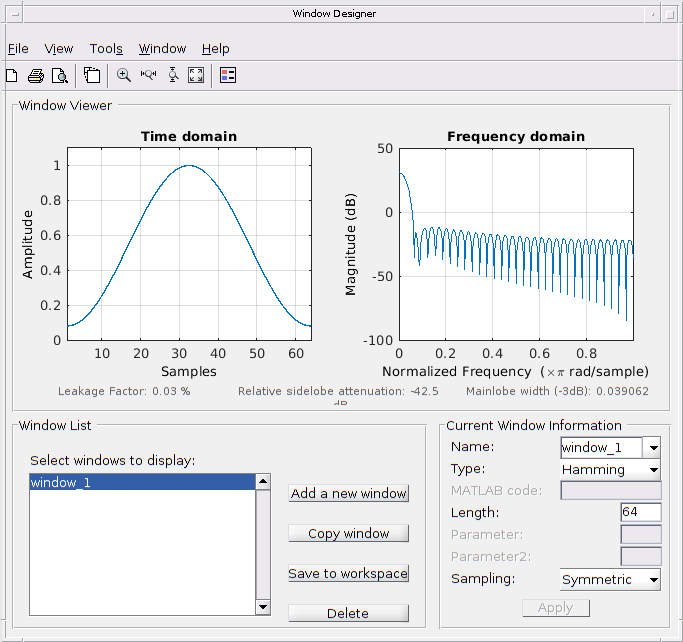

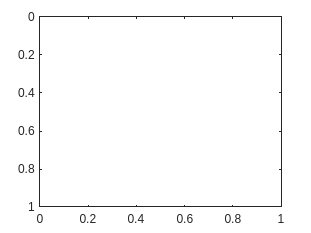

% Find the window around the red car
window_red = img{1}(359:430,688:770);
figure, imagesc(window), colormap gray


% % Pint all the photos of the red car
% for k = 1:6
%     RectDetection(window_red, img{k});
% end

Find the black car

% % This window is too small
% window_black1 = img{1}(380:400, 575:620);
% figure, imagesc(window_black1), colormap gray;
% 
% % Pint all the photos of the black car, smoller window
% for k = 1:6
%     RectDetection(window_black1, img{k});
% end

% % This is a good window, it catch the car wile it turns
% window_black2 = img{1}(375:410, 570:615);
% figure, imagesc(window_black2), colormap gray;
% 
% % Pint all the photos of the black car, normal window
% for k = 1:6
%     RectDetection(window_black2, img{k});
% end
% 
% %
% window_black3 = img{1}(360:420, 555:645);
% figure, imagesc(window_black3), colormap gray;
% 
% % Pint all the photos of the black car, bigger window
% for k = 1:6
%     RectDetection(window_black3, img{k});
% end


Punto 2

% %Harris corner detector
% 
% tmp=imread('Image1.png');

Error using imread>get_full_filename
File "Image1.png" does not exist.

Error in imread (line 372)
        fullname = get_full_filename(filename);

% I=double(tmp);
% figure,imagesc(I),colormap gray
% 
% %compute x and y derivative of the image
% dx=[1 0 -1; 2 0 -2; 1 0 -1];
% dy=[1 2 1; 0  0  0; -1 -2 -1];
% Ix=conv2(I,dx,'same');
% Iy=conv2(I,dy,'same');
% figure,imagesc(Ix),colormap gray,title('Ix')
% figure,imagesc(Iy),colormap gray,title('Iy')
% 
% %compute products of derivatives at every pixel
% Ix2=Ix.*Ix; Iy2=Iy.*Iy; Ixy=Ix.*Iy;
% 
% %compute the sum of products of  derivatives at each pixel
% g = fspecial('gaussian', 9, 1.2);
% figure,imagesc(g),colormap gray,title('Gaussian')
% Sx2=conv2(Ix2,g,'same'); Sy2=conv2(Iy2,g,'same'); Sxy=conv2(Ixy,g,'same');
% 
% %features detection
% [rr,cc]=size(Sx2);
% edge_reg=zeros(rr,cc); corner_reg=zeros(rr,cc); flat_reg=zeros(rr,cc);
% R_map=zeros(rr,cc);
% k=0.05;
% 
% for ii=1:rr
%     for jj=1:cc
%         %define at each pixel x,y the matrix
%         M=[Sx2(ii,jj),Sxy(ii,jj);Sxy(ii,jj),Sy2(ii,jj)];
%         %compute the response of the detector at each pixel
%         R=det(M) - k*(trace(M).^2);
%         R_map(ii,jj)=R;
%         %threshod on value of R
%         if R<-300000
%             edge_reg(ii,jj)=1;
%         elseif R>3000000
%             corner_reg(ii,jj)=1;
%         else
%             flat_reg(ii,jj)=1;
%         end
%     end
% end
% 
% figure,imagesc(edge_reg.*I),colormap gray,title('edge regions')
% figure,imagesc(corner_reg.*I),colormap gray,title('corner regions')
% figure,imagesc(flat_reg.*I),colormap gray,title('flat regions')
% figure,imagesc(R_map),colormap jet,title('R map')
% 
% 
% 
% 







function [img] = colorToDouble (img)
%Function that transform the image rom color to gray
    
    img = rgb2gray(img);
    img = double(img);
end

function RectDetection (window, img)

%Do the NCC with the image and the window
c = normxcorr2(window,img);
%figure, imagesc(c), colormap gray, title("image cross correlated");

% Find the peak in cross correlation(white point)
[ypeak,xpeak] = find(c==max(c(:)));

yoffSet = ypeak-size(window,1);
xoffSet = xpeak-size(window,2);

figure, imagesc(img), colormap("gray");
hold on
rectangle('Position',[xoffSet yoffSet size(window,2) size(window,1)],"LineWidth",2, "EdgeColor",[1 0 0] )
end






